**INIT**

close all; clear all;

**GLOBAL VARS**

alpha = 0.1;
entropyArea = 9;

**READ ORIGINAL IMAGE**

image = imread('../res/image.tif','tif');
[dimx,dimy] = size(image);
imageDouble   = double(image);

**READ WATERMARK**

wSize = 1024;
w = open("../res/pufferfish.mat");
watermark = w.w;
flatWatermark = reshape(watermark, 1, wSize);

**FILTER ENTROPY**

[minEnt, entSize, entropyMatrix, entropySorted, entropyIndexes] = filterEntropy(image, entropyArea, dimx, dimy);

**APPLY WATERMARK**

watImage = reshape(image, 1, dimx*dimy);
for i = 1:wSize
    index = entropyIndexes(i);
    originalPixel = image(index);
    entropy = entropySorted(i);
    strength = (entropy - minEnt)/entSize;
    watImage(index) = originalPixel + strength * alpha * watermark(i)*originalPixel;
end
watImage = reshape(watImage, dimx, dimy);

**SHOW RESULTS**

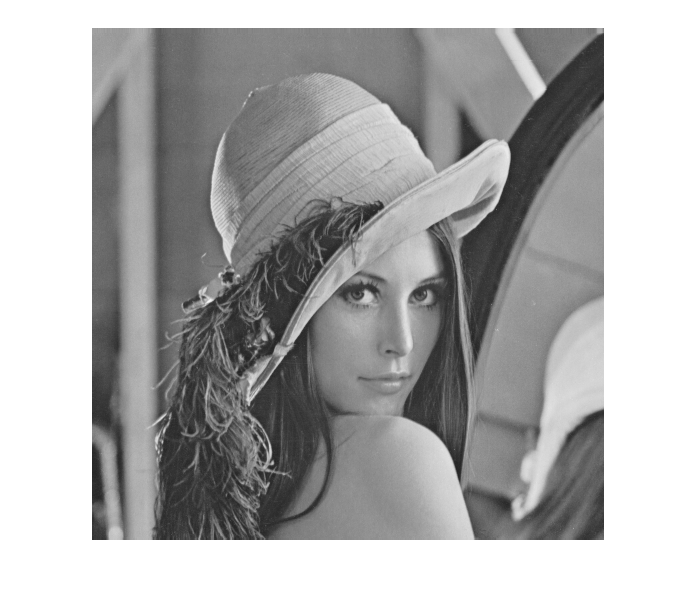

imshow(image);

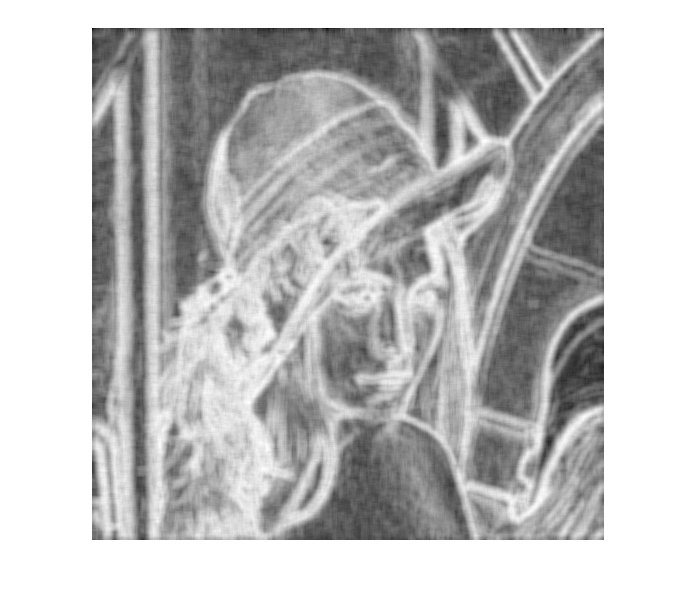

imshow(entropyMatrix, []);

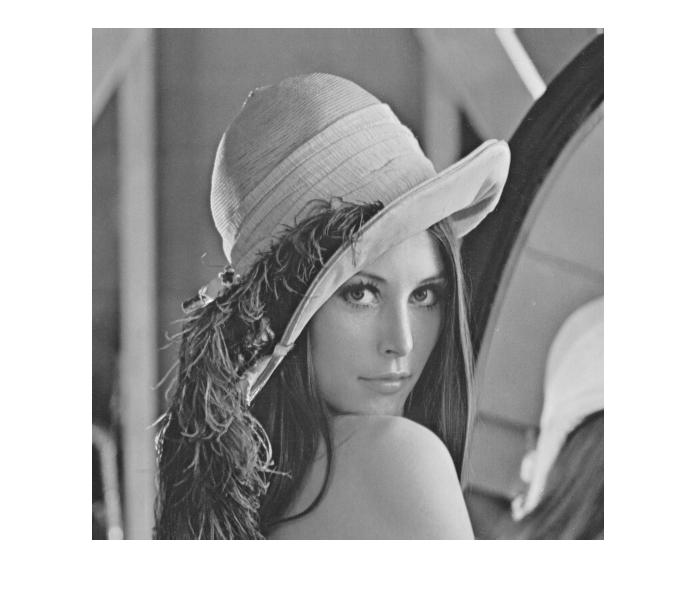

imshow(watImage);

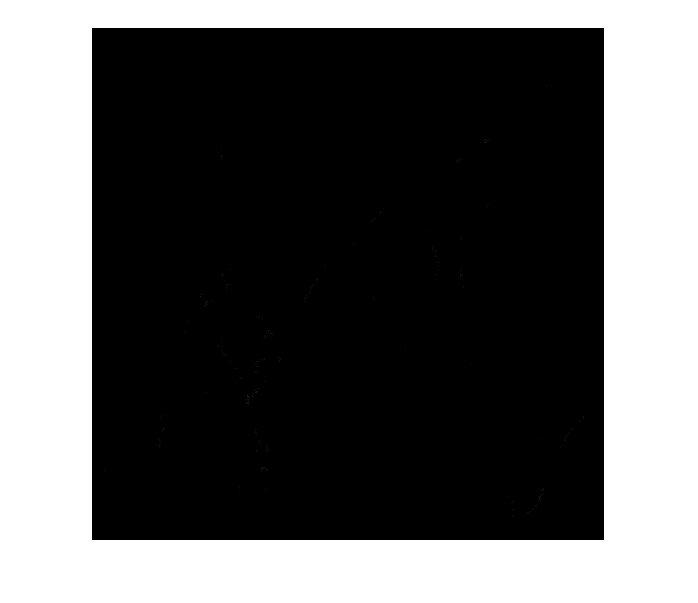

imshow(watImage-image);

WPSNR(image, watImage)

ans = 63.3599

PSNR(image, watImage)

PSNR = +53.10 dB


**SAVE RESULTS**

imwrite(uint8(watImage),'../output/watImage.tif','tif');